# Faza 1

## Punctul a)

% set(groot, 'DefaultFigureUnits', 'pixels');
set(groot, 'DefaultFigurePosition', [20, 20, 1500, 1000]);
% Instructiune initializare proprietati pentru toate graficele (utila sa
% pot sa maximizez dimensiunile ferestrelor. Asta e folosita pentru
% afisarea graficelor intr-un mod corespunzator in live script, si pentru
% export in PDF. Eventual aceste marimi pot fi modificate.
[window_length, r_ceb, beta_k, L, alpha_t] = PS_PRJ_1_Faza_1(4, 3);
% Afisarea parametrilor in interiorul documentului pentru verificare.
fprintf("M = %d\nr(Cebisev) = %f\nbeta(Kaiser) = %d\nL(Lanczos) = %d\nalpha(Tukey) = %f", ...
    window_length, r_ceb, beta_k, L, alpha_t);

M = 34
r(Cebisev) = 90.756757
beta(Kaiser) = 6.302703e+00
L(Lanczos) = 6
alpha(Tukey) = 52.270270

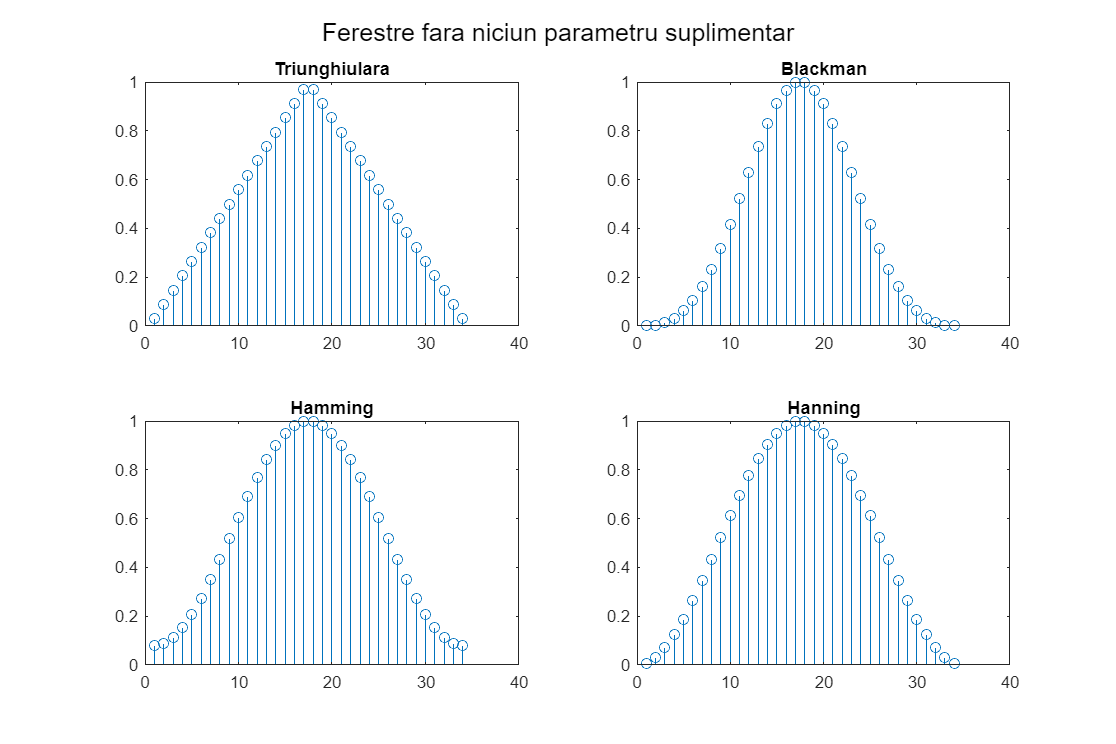

% Ferestrele fara parametrii aditionali (dreptunghiular nu e inclus 
% asa cum este precizat in indicatii.
fig1 = figure('Name', 'Ferestre fara niciun parametru suplimentar');
sgtitle('Ferestre fara niciun parametru suplimentar');
subplot(2, 2, 1);
w_triang = triang(window_length);
stem(w_triang);
title('Triunghiulara');
subplot(2, 2, 2);
w_blackman = blackman(window_length);
stem(w_blackman);
title('Blackman');
subplot(2, 2, 3);
w_hamm = hamming(window_length);
stem(w_hamm);
title('Hamming');
subplot(2, 2, 4);
w_hann = hanning(window_length);
stem(w_hann);
title('Hanning');

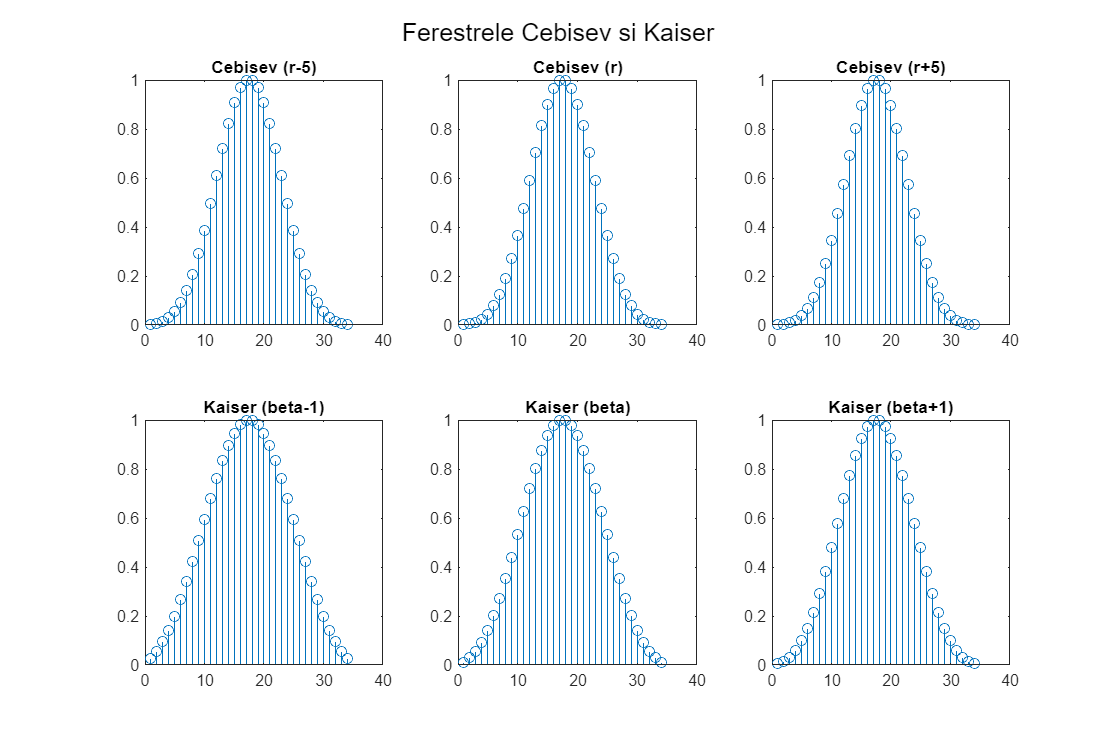

% Cebisev si Kaiser
fig2 = figure('Name', 'Ferestrele Cebisev si Kaiser');
sgtitle('Ferestrele Cebisev si Kaiser');
subplot(2, 3, 1);
w_cheb_inf = chebwin(window_length, r_ceb-5);
stem(w_cheb_inf);
title('Cebisev (r-5)');
subplot(2, 3, 2);
w_cheb = chebwin(window_length, r_ceb);
stem(w_cheb);
title('Cebisev (r)');
subplot(2, 3, 3);
w_cheb_sup = chebwin(window_length, r_ceb+5);
stem(w_cheb_sup);
title('Cebisev (r+5)');
subplot(2, 3, 4);
w_kaiser_inf = kaiser(window_length, beta_k - 1);
stem(w_kaiser_inf);
title('Kaiser (beta-1)');
subplot(2, 3, 5);
w_kaiser = kaiser(window_length, beta_k);
stem(w_kaiser);
title('Kaiser (beta)');
subplot(2, 3, 6);
w_kaiser_sup = kaiser(window_length, beta_k + 1);
stem(w_kaiser_sup);
title('Kaiser (beta+1)');

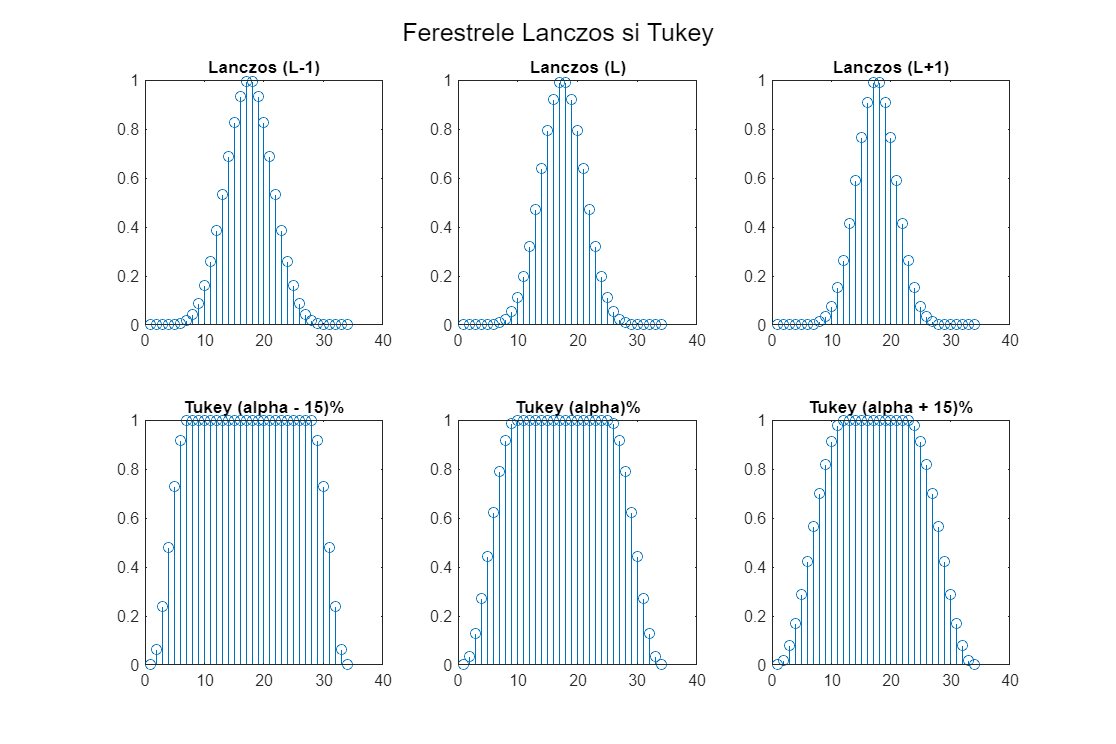

% Lanczos si Tukey
fig3 = figure('Name', 'Ferestrele Lanczos si Tukey');
sgtitle('Ferestrele Lanczos si Tukey');
subplot(2, 3, 1);
w_lanczos_inf = lanczoswin(window_length, L - 1);
stem(w_lanczos_inf);
title('Lanczos (L-1)');
subplot(2, 3, 2);
w_lanczos = lanczoswin(window_length, L);
stem(w_lanczos);
title('Lanczos (L)');
subplot(2, 3, 3);
w_lanczos_sup = lanczoswin(window_length, L + 1);
stem(w_lanczos_sup);
title('Lanczos (L+1)');
subplot(2, 3, 4);
w_tukey_inf = tukeywin(window_length, (alpha_t - 15) / 100);
stem(w_tukey_inf);
title('Tukey (alpha - 15)%');
subplot(2, 3, 5);
w_tukey = tukeywin(window_length, alpha_t / 100);
stem(w_tukey);
title('Tukey (alpha)%');
subplot(2, 3, 6);
w_tukey_sup = tukeywin(window_length, (alpha_t + 15) / 100);
stem(w_tukey_sup);
title('Tukey (alpha + 15)%');

Formele ferestrelor sunt asemanatoare cu descrierea din cadrul materialului de urmat din laborator. Intre ferestrele cu parametru aditional, acolo unde am facut modificari cu acele marje, nu am observat vreo diferenta majora pe graficul ferestrelor.

## Punctul b)

De la acest punct, pentru a fi mai clar atunci cand se deseneaza figurile, concret ce reprezinta fiecare grafic este determinat de titlu, apoi pentru fiecare subplot, titlul lui este pentru ce fereastra se reprezinta acel lucru.

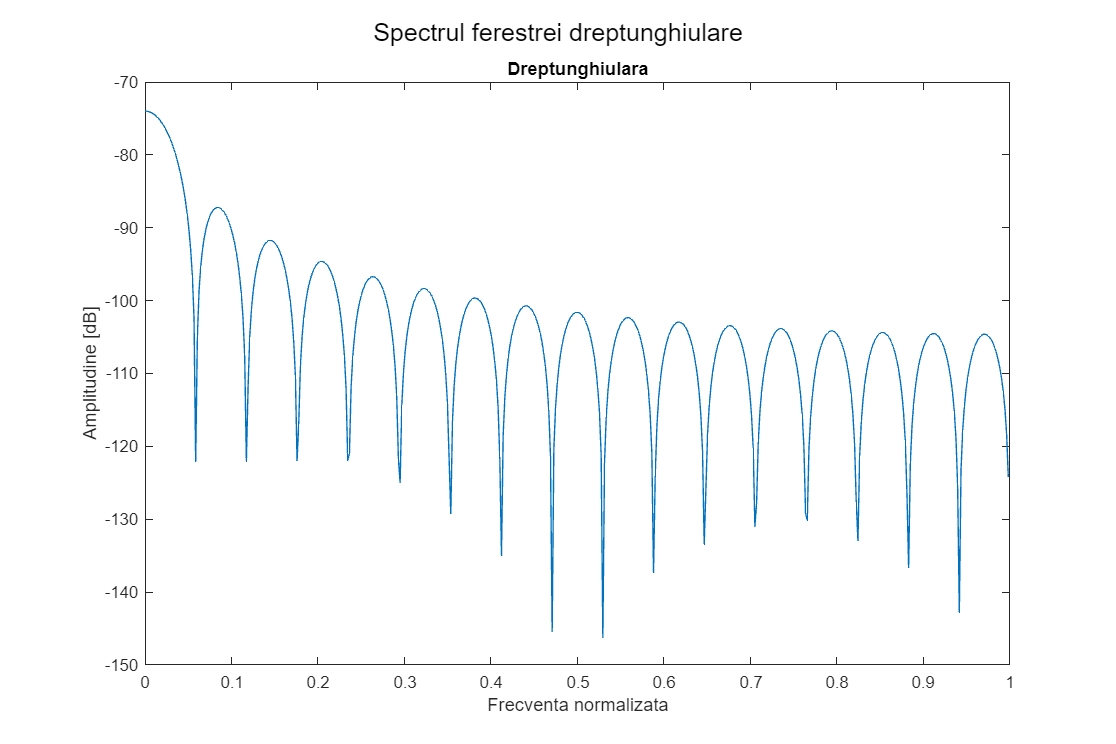

freqz_rez = 5000; % Rezolutie raspuns FFT.
% Am uitat sa adaug figura pentru fereastra dreptunghiulara, si aici o sa
% fie decalaj al numerotarii figurilor.
fig_drept = figure('Name', 'Spectrul ferestrei dreptunghiulare');
w_rectg = rectwin(window_length);
w_rectg = w_rectg / sum(w_rectg);
[H, ang] = freqz(w_rectg, freqz_rez);
subplot(1, 1, 1);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Dreptunghiulara');
sgtitle('Spectrul ferestrei dreptunghiulare');

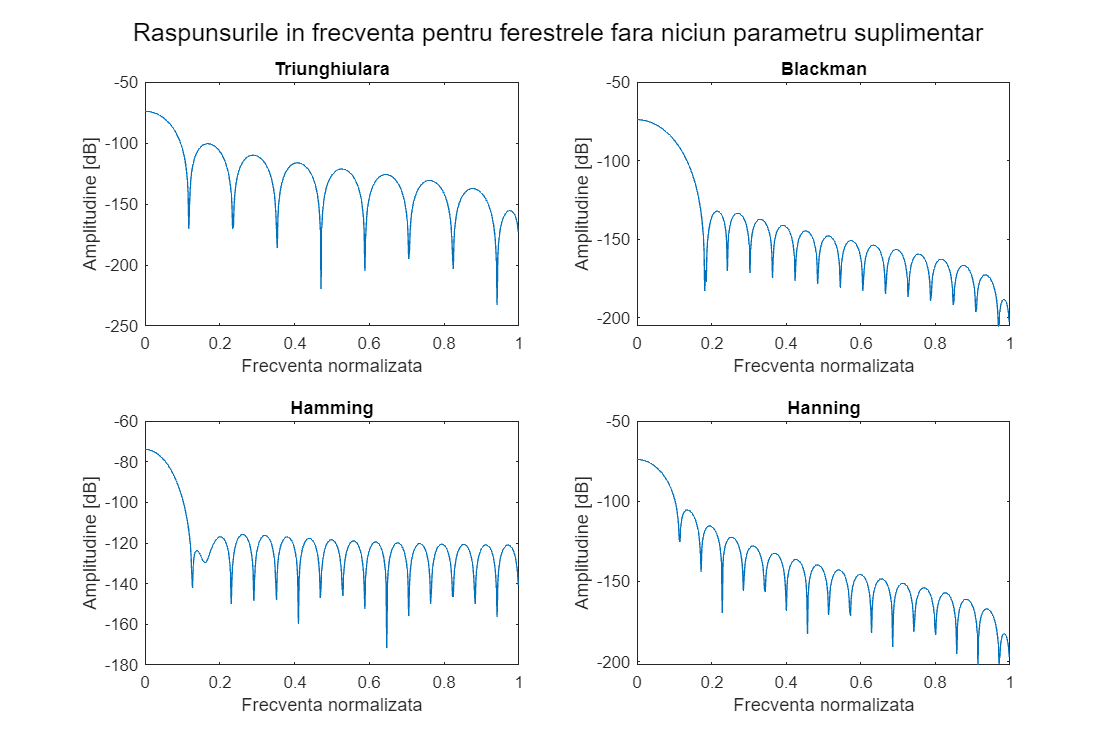

fig4 = figure('Name', ['Raspunsurile in frecventa pentru ferestrele ' ...
    'fara niciun parametru suplimentar']);
sgtitle('Raspunsurile in frecventa pentru ferestrele fara niciun parametru suplimentar');
subplot(2, 2, 1);
w_triang = w_triang / sum(w_triang);
[H, ang] = freqz(w_triang, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Triunghiulara');
subplot(2, 2, 2);
w_blackman = w_blackman / sum(w_blackman);
[H, ang] = freqz(w_blackman, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Blackman');
subplot(2, 2, 3);
w_hamm = w_hamm / sum(w_hamm);
[H, ang] = freqz(w_hamm, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Hamming');
subplot(2, 2, 4);
w_hann = w_hann / sum(w_hann);
[H, ang] = freqz(w_hann, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Hanning');

De aici este clar ca fereastra triunghiulara are cea mai mica estompare (lobii secundari apropiati ca amplitudine fata de cel principal). Ferestrele Blackman si Hanning sunt similare, cu Blackman avand estomparea amplitudinii lobului principal foarte mare, si cu lobii secundari similar de scunzi. Hamming are lobul principal cu o scadere buna, doar ca lobii secundari sunt mult mai inalti fata de Blackman si Hanning.

fig5 = figure('Name', 'Raspunsul in frecventa pentru ferestrele Cebisev si Kaiser');
sgtitle('Raspunsul in frecventa pentru ferestrele Cebisev si Kaiser');
subplot(2, 3, 1);
w_cheb_inf = w_cheb_inf / sum(w_cheb_inf);
[H, ang] = freqz(w_cheb_inf, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Cebisev (r-5)');
subplot(2, 3, 2);
w_cheb = w_cheb / sum(w_cheb);
[H, ang] = freqz(w_cheb, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Cebisev (r)');
subplot(2, 3, 3);
w_cheb_sup = w_cheb_sup / sum(w_cheb_sup);
[H, ang] = freqz(w_cheb_sup, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Cebisev (r+5)');

Cand modificam parametrul "r" al ferestrei Cebisev, observam ca modificarile nu au vreo corelanta cu modalitatea in care se schimba raspunsul. Pentru "r" generat, avem cea mai buna scadere a lobului principal, in timp ce latimea lui nu se modifica considerabil, in schimb lobii secundari sunt diferiti de la grafic la grafic, fara vreun fel de relatie cu "r".

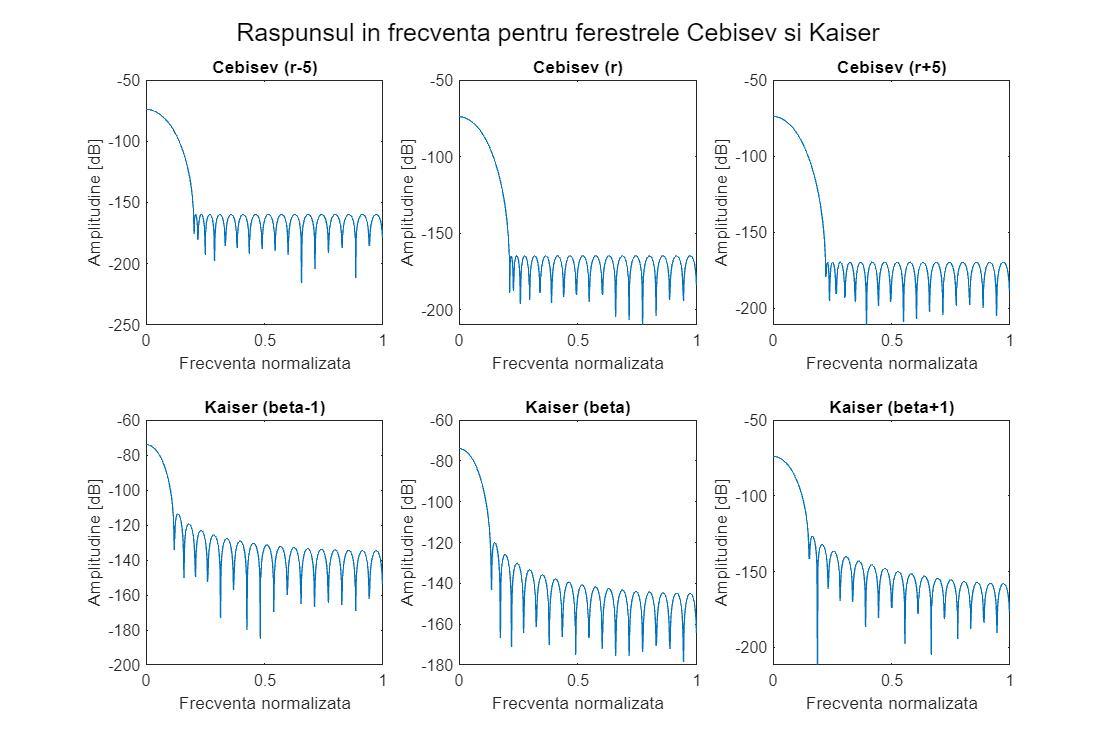

subplot(2, 3, 4);
w_kaiser_inf = w_kaiser_inf / sum(w_kaiser_inf);
[H, ang] = freqz(w_kaiser_inf, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Kaiser (beta-1)');
subplot(2, 3, 5);
w_kaiser = w_kaiser / sum(w_kaiser);
[H, ang] = freqz(w_kaiser, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Kaiser (beta)');
subplot(2, 3, 6);
w_kaiser_sup = w_kaiser_sup / sum(w_kaiser_sup);
[H, ang] = freqz(w_kaiser_sup, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Kaiser (beta+1)');

Pentru fereastra Kaiser, observam ca atunci cand crestem coeficientul $\beta$ se modifia si caderea lobului principal, insa exista posibilitatea ca in cazul $\beta + 1$ sa avem situatia in care scaderea lobului principal sa influenteze cresterea celor secundari datorita fenomenului de incertitudine Gabor-Heisenberg.

fig6 = figure('Name', 'Raspunsul in frecventa pentru ferestrele Lanczos si Tukey');
sgtitle('Raspunsul in frecventa pentru ferestrele Lanczos si Tukey');
subplot(2, 3, 1);
w_lanczos_inf = w_lanczos_inf / sum(w_lanczos_inf);
[H, ang] = freqz(w_lanczos_inf, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Lanczos (L-1)');
subplot(2, 3, 2);
w_lanczos = w_lanczos / sum(w_lanczos);
[H, ang] = freqz(w_lanczos, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Lanczos (L)');
subplot(2, 3, 3);
w_lanczos_sup = w_lanczos_sup / sum(w_lanczos_sup);
[H, ang] = freqz(w_lanczos_sup, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Lanczos (L+1)');

Pentru parametrul "L" observam ca cresterea lui induce o deschidere a lobului principal, adica scaderea este mai mare, dar si latimea lui creste. Inaltimea lobilor secundari este modificata doar din punct de vedere a inceperii lor, dar inaltimea lor nu este afectata atat de mult. Presupun ca pe grafic anumite variatii apar si din cauza aproximarii numerice.

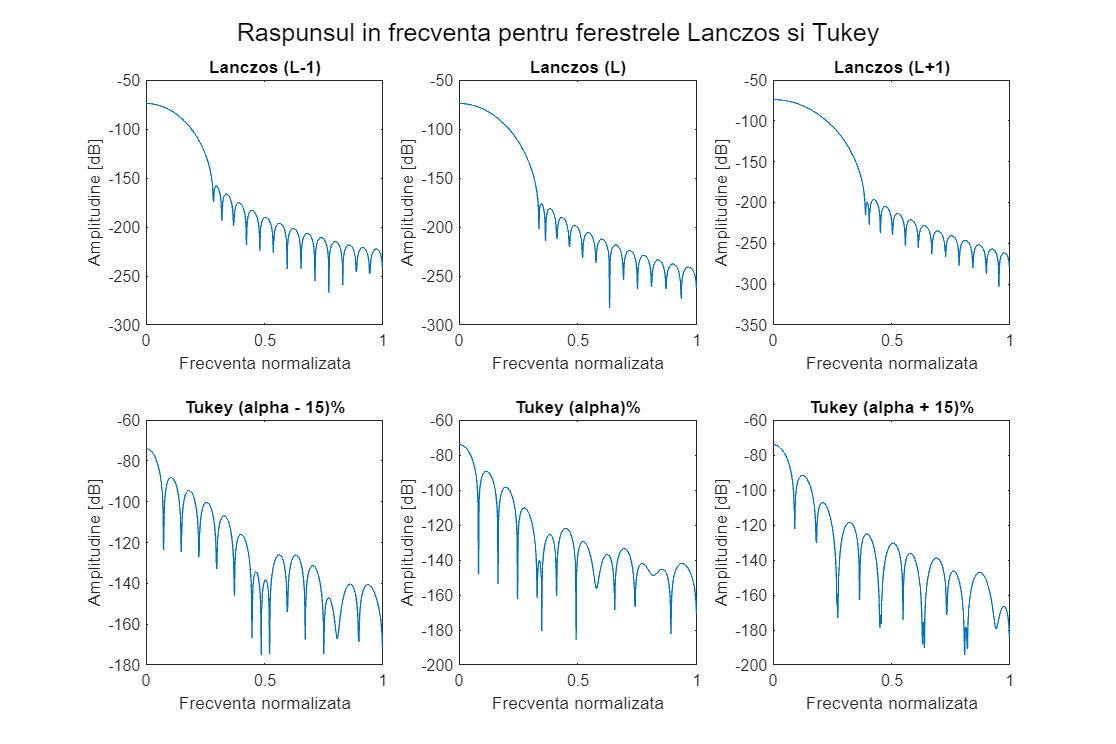

subplot(2, 3, 4);
w_tukey_inf = w_tukey_inf / sum(w_tukey_inf);
[H, ang] = freqz(w_tukey_inf, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Tukey (alpha - 15)%');
subplot(2, 3, 5);
w_tukey = w_tukey / sum(w_tukey);
[H, ang] = freqz(w_tukey, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Tukey (alpha)%');
subplot(2, 3, 6);
w_tukey_sup = w_tukey_sup / sum(w_tukey_sup);
[H, ang] = freqz(w_tukey_sup, freqz_rez);
plot(ang / pi, mag2db(abs(H)));
xlabel('Frecventa normalizata')
ylabel('Amplitudine [dB]');
title('Tukey (alpha + 15)%');

Se poate observa ca fereastra Tukey nu are un randament foarte bun, iar raspunsul in frecventa este imprevizibil, cu lobi secundari de diferite marimi. De observat totusi ca aprametrul $\alpha$ nu are un efect proportional cu scaderea lobului principal (cel mai bun rezultat dintre cele 3 e cel din mijloc, pentru o valoare generata $\approx 52\%$.

## Punctul c)

Mai sus am prezentat caracterestici ale ferestrelor si particularitati pentru parametrii diferiti (acolo unde e cazul). Avand in vedere cele precizate, putem trage anumite concluzii:

- De evitat ferestrele dreptunghiulare, triunghiulare si Tukey;

- Fereastra Hamming are comportament similar cu Cebisev, dar un randament mai prost. Similar pentru Hanning, Blackman ii este superior;

- Nu e obligatoriu ca toti parametrii aditionali pentru ferestrele Cebisev, Kaiser, Lanczos si Tukey sa aba relatii de proportionalitate cu amplitudinile raspunsurilor ferestrelor (fenomenul de care suntem de fapt interesati). Putem avea cazul Tukey, unde variatia este asa de haotica incat nu se poate determina nicio concluzie. Putem avea si cazul Lanczos unde parametrul L este direct proportional cu scaderea lobului principal si cresterea lui in latime, deci invers proportional cu cresterea lobilor secundari.

# Faza 2

## Punctul a)

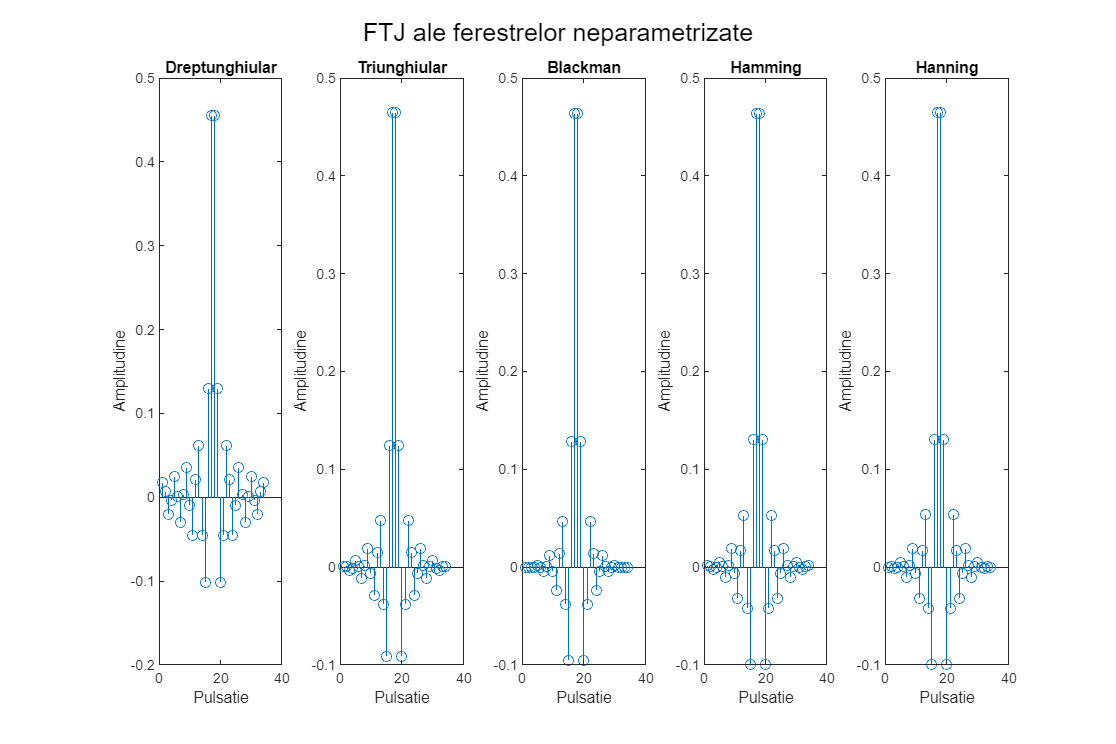

omega_c = PS_PRJ_1_Faza_2a(4, 3);
freq_c = omega_c / pi;
% Am declarat inainte toate figurile ca sa nu recalculez FTJ pentru fiecare
% fereastra cand trebuie puse in figurile lor.
fig7 = figure('Name', 'FTJ ale ferestrelor neparametrizate');
fig8 = figure('Name', 'FTJ ale ferestrelor Cebisev si Kaiser');
fig9 = figure('Name', 'FTJ ale ferestrelor Lanczos si Tukey');
fig10 = figure('Name', 'Spectrele FTJurilor ale ferestrelor neparametrizate');
fig11 = figure('Name', 'Spectrele FTJurilor ale ferestrelor Cebisev si Kaiser');
fig12 = figure('Name', 'Spectrele FTJurilor ale ferestrelor Lanczos si Tukey');
figcompare = figure('Name', 'Compararea spectrelor FTJurilor');
% FTJ dreptunghiular
h = fir1(window_length - 1, freq_c, w_rectg);
figure(fig7);
subplot(1, 5, 1);
stem(h);
title('Dreptunghiular')
xlabel('Pulsatie');
ylabel('Amplitudine');
figure(fig10);
[H, om] = freqz(h, freqz_rez);
subplot(2, 5, 1);
plot(om / pi, mag2db(abs(H)));
title('Dreptunghiular');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(2, 5, 6);
plot(om / pi, angle(H));
title('Dreptunghiular');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
figure(figcompare);
plot(om / pi, mag2db(abs(H)), 'DisplayName', 'Dreptunghiular', 'Color', '#6e6e6e');
hold on % Doar pentru "figcompare"
% FTJ triunghiular
h = fir1(window_length - 1, freq_c, w_triang);
figure(fig7);
subplot(1, 5, 2);
stem(h);
title('Triunghiular')
xlabel('Pulsatie');
ylabel('Amplitudine');
figure(fig10);
[H, om] = freqz(h, freqz_rez);
subplot(2, 5, 2);
plot(om / pi, mag2db(abs(H)));
title('Triunghiular');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(2, 5, 7);
plot(om / pi, angle(H));
title('Triunghiular');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
figure(figcompare);
plot(om / pi, mag2db(abs(H)), 'DisplayName', 'Triunghiular', 'Color', '#ff2bbc');
% FTJ Blackman
h = fir1(window_length - 1, freq_c, w_blackman);
figure(fig7);
subplot(1, 5, 3);
stem(h);
title('Blackman')
xlabel('Pulsatie');
ylabel('Amplitudine');
figure(fig10);
[H, om] = freqz(h, freqz_rez);
subplot(2, 5, 3);
plot(om / pi, mag2db(abs(H)));
title('Blackman');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(2, 5, 8);
plot(om / pi, angle(H));
title('Blackman');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
figure(figcompare);
plot(om / pi, mag2db(abs(H)), 'DisplayName', 'Blackman', 'Color', '#8f02fa');
% FTJ Hamming
h = fir1(window_length - 1, freq_c, w_hamm);
figure(fig7);
subplot(1, 5, 4);
stem(h);
title('Hamming')
xlabel('Pulsatie');
ylabel('Amplitudine');
figure(fig10);
[H, om] = freqz(h, freqz_rez);
subplot(2, 5, 4);
plot(om / pi, mag2db(abs(H)));
title('Hamming');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(2, 5, 9);
plot(om / pi, angle(H));
title('Hamming');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
figure(figcompare);
plot(om / pi, mag2db(abs(H)), 'DisplayName', 'Hamming', 'Color', '#00cfc8');
% FTJ Hanning
h = fir1(window_length - 1, freq_c, w_hann);
figure(fig7);
subplot(1, 5, 5);
stem(h);
title('Hanning')
xlabel('Pulsatie');
ylabel('Amplitudine');
sgtitle('FTJ ale ferestrelor neparametrizate');

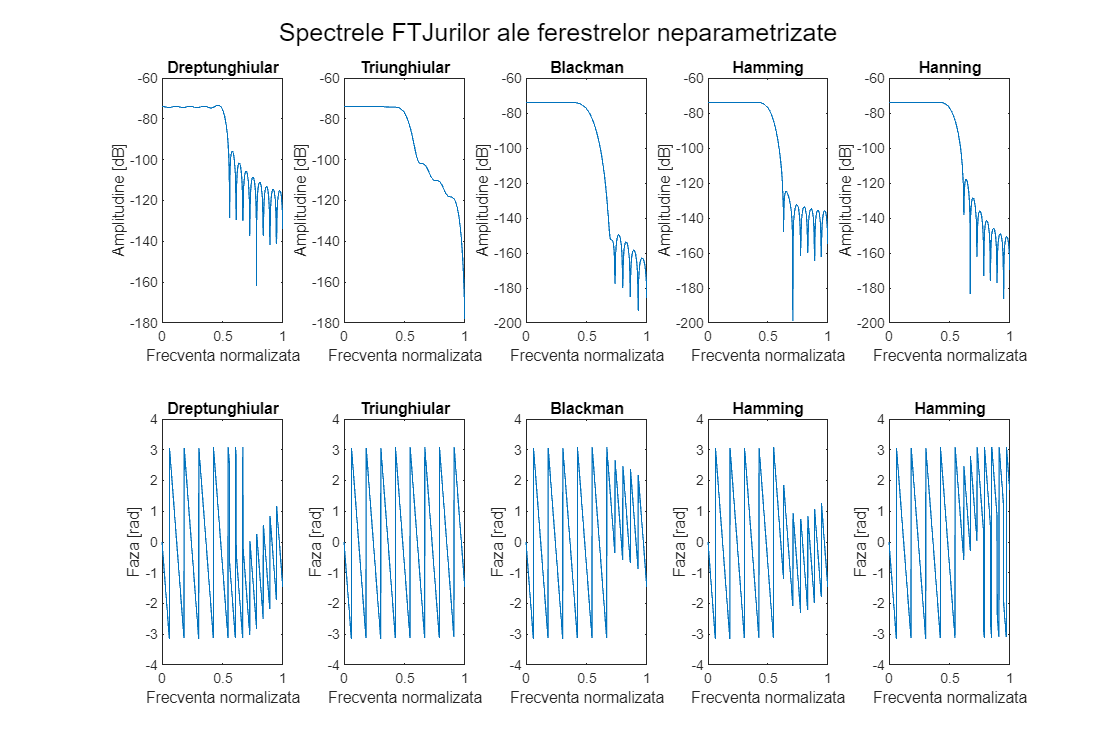

figure(fig10);
[H, om] = freqz(h, freqz_rez);
subplot(2, 5, 5);
plot(om / pi, mag2db(abs(H)));
title('Hanning');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(2, 5, 10);
plot(om / pi, angle(H));
title('Hamming');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
sgtitle('Spectrele FTJurilor ale ferestrelor neparametrizate');

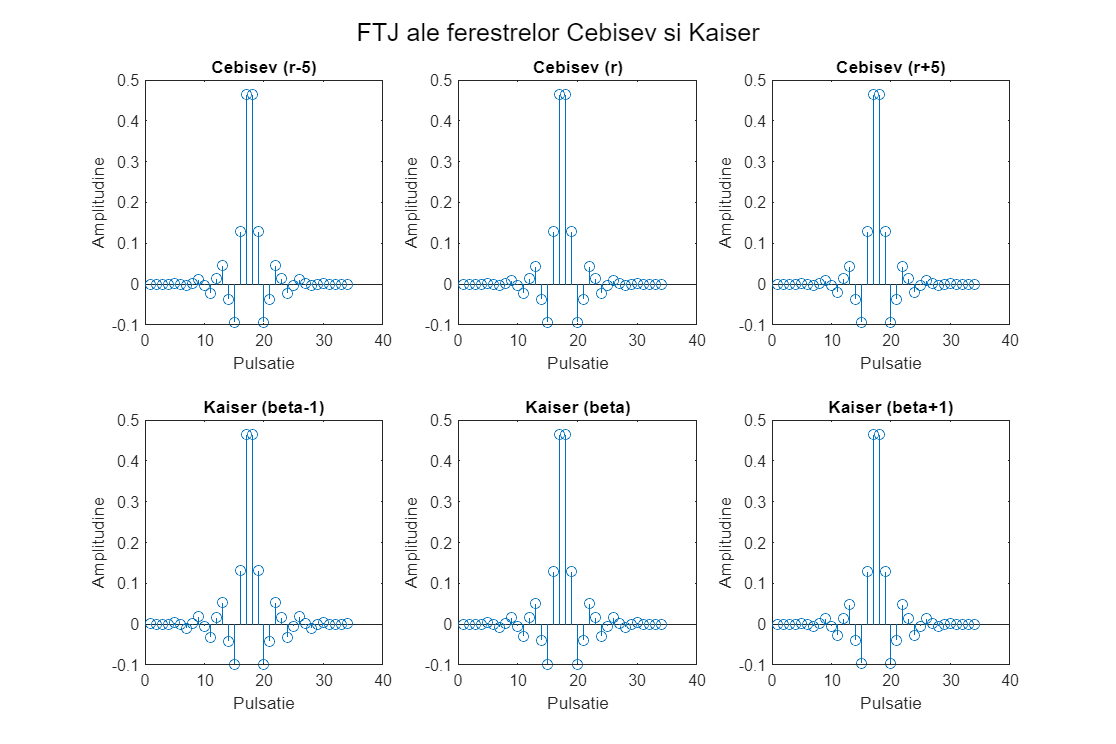

figure(figcompare);
plot(om / pi, mag2db(abs(H)), 'DisplayName', 'Hanning', 'Color', '#007874');
%FTJ Cebisev (toate variatiile)
h_inf = fir1(window_length - 1, freq_c, w_cheb_inf);
h = fir1(window_length - 1, freq_c, w_cheb);
h_sup = fir1(window_length - 1, freq_c, w_cheb_sup);
[H_inf, om_inf] = freqz(h_inf, freqz_rez);
[H, om] = freqz(h, freqz_rez);
[H_sup, om_sup] = freqz(h_sup, freqz_rez);
figure(fig8);
subplot(2, 3, 1);
stem(h_inf);
title('Cebisev (r-5)');
xlabel('Pulsatie');
ylabel('Amplitudine');
subplot(2, 3, 2);
stem(h);
title('Cebisev (r)');
xlabel('Pulsatie');
ylabel('Amplitudine');
subplot(2, 3, 3);
stem(h_sup);
title('Cebisev (r+5)');
xlabel('Pulsatie');
ylabel('Amplitudine');
figure(fig11);
subplot(3, 4, 1);
plot(om_inf / pi, mag2db(abs(H_inf)));
title('Cebisev (r-5)');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(3, 4, 5);
plot(om / pi, mag2db(abs(H)));
title('Cebisev (r)');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(3, 4, 9);
plot(om_sup / pi, mag2db(abs(H_sup)));
title('Cebisev (r+5)');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(3, 4, 2);
plot(om_inf / pi, angle(H_inf));
title('Cebisev (r - 5)');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
subplot(3, 4, 6);
plot(om / pi, angle(H));
title('Cebisev (r)');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
subplot(3, 4, 10);
plot(om_sup / pi, angle(H_sup));
title('Cebisev (r + 5)');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
figure(figcompare);
plot(om / pi, mag2db(abs(H_inf)), 'DisplayName', 'Cebisev (r-5)', 'Color', '#acff75');
plot(om / pi, mag2db(abs(H)), 'DisplayName', 'Cebisev (r)', 'Color', '#66ff00');
plot(om / pi, mag2db(abs(H_sup)), 'DisplayName', 'Cebisev (r+5)', 'Color', '#368700');
%FTJ Kaiser (toate variatiile)
h_inf = fir1(window_length - 1, freq_c, w_kaiser_inf);
h = fir1(window_length - 1, freq_c, w_kaiser);
h_sup = fir1(window_length - 1, freq_c, w_kaiser_sup);
[H_inf, om_inf] = freqz(h_inf, freqz_rez);
[H, om] = freqz(h, freqz_rez);
[H_sup, om_sup] = freqz(h_sup, freqz_rez);
figure(fig8);
subplot(2, 3, 4);
stem(h_inf);
title('Kaiser (beta-1)');
xlabel('Pulsatie');
ylabel('Amplitudine');
subplot(2, 3, 5);
stem(h);
title('Kaiser (beta)');
xlabel('Pulsatie');
ylabel('Amplitudine');
subplot(2, 3, 6);
stem(h_sup);
title('Kaiser (beta+1)');
xlabel('Pulsatie');
ylabel('Amplitudine');
sgtitle('FTJ ale ferestrelor Cebisev si Kaiser');

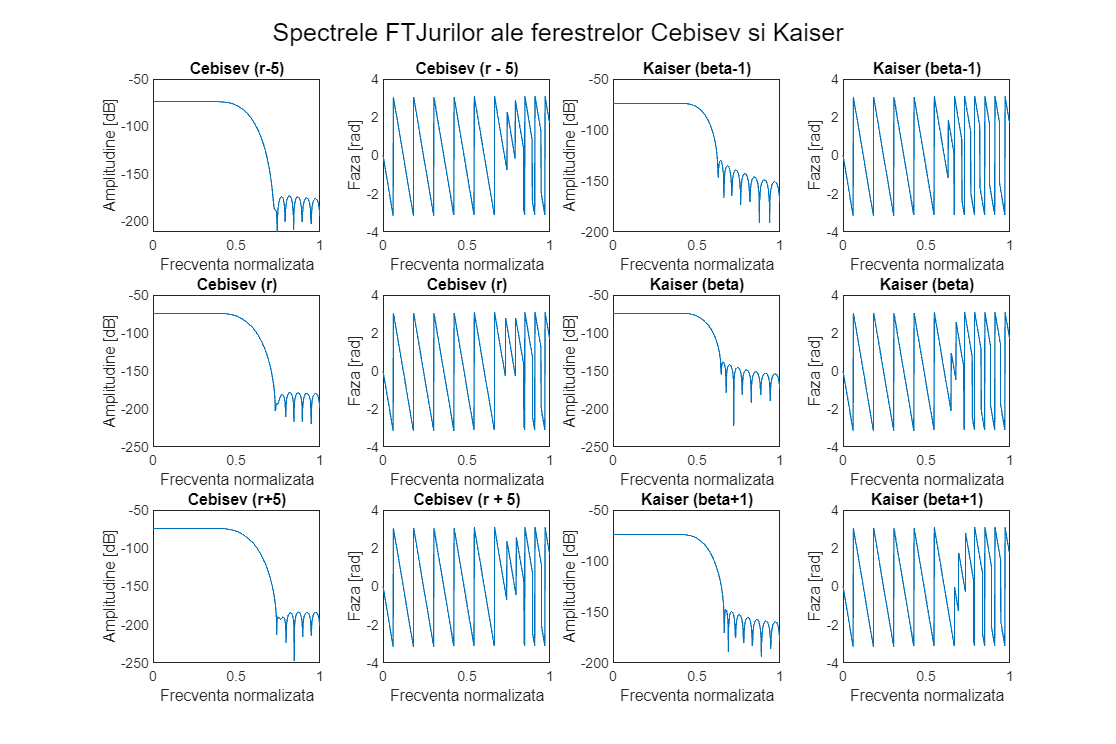

figure(fig11);
subplot(3, 4, 3);
plot(om_inf / pi, mag2db(abs(H_inf)));
title('Kaiser (beta-1)');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(3, 4, 7);
plot(om / pi, mag2db(abs(H)));
title('Kaiser (beta)');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(3, 4, 11);
plot(om_sup / pi, mag2db(abs(H_sup)));
title('Kaiser (beta+1)');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(3, 4, 4);
plot(om_inf / pi, angle(H_inf));
title('Kaiser (beta-1)');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
subplot(3, 4, 8);
plot(om / pi, angle(H));
title('Kaiser (beta)');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
subplot(3, 4, 12);
plot(om_sup / pi, angle(H_sup));
title('Kaiser (beta+1)');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
sgtitle('Spectrele FTJurilor ale ferestrelor Cebisev si Kaiser');

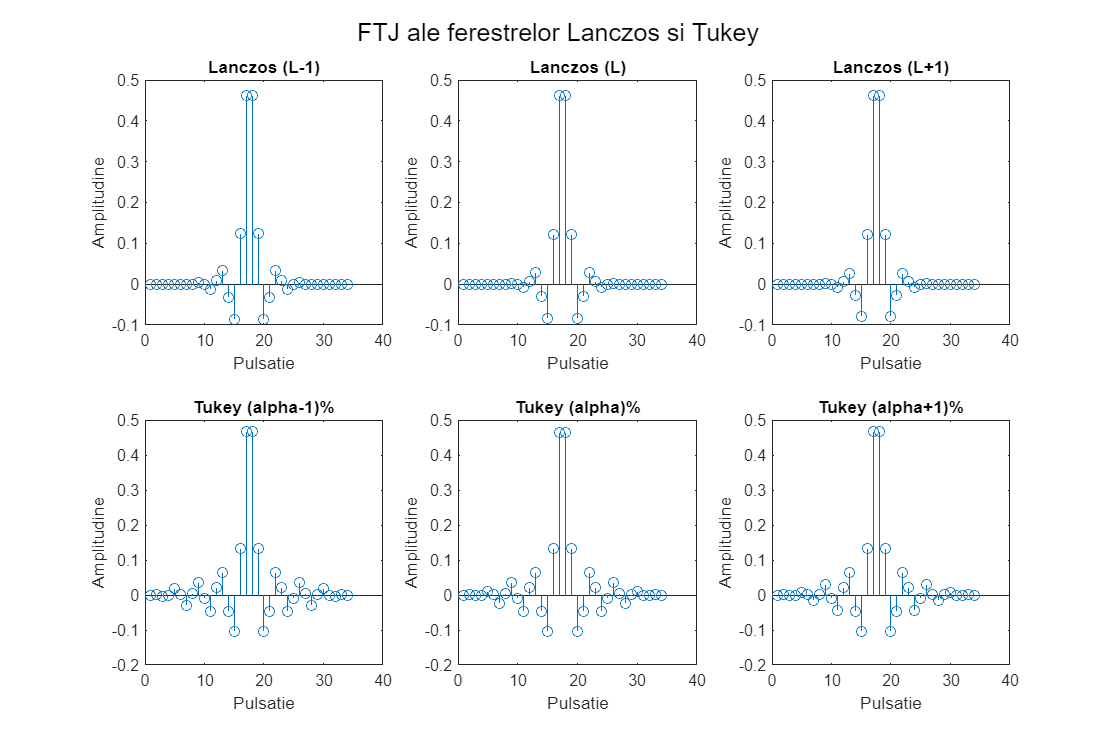

figure(figcompare);
plot(om / pi, mag2db(abs(H_inf)), 'DisplayName', 'Kaiser (beta-1)', 'Color', '#6e90ff');
plot(om / pi, mag2db(abs(H)), 'DisplayName', 'Kaiser (beta)', 'Color', '#003cff');
plot(om / pi, mag2db(abs(H_sup)), 'DisplayName', 'Kaiser (beta+1)', 'Color', '#002087');
%FTJ Lanczos (toate variatiile)
h_inf = fir1(window_length - 1, freq_c, w_lanczos_inf);
h = fir1(window_length - 1, freq_c, w_lanczos);
h_sup = fir1(window_length - 1, freq_c, w_lanczos_sup);
[H_inf, om_inf] = freqz(h_inf, freqz_rez);
[H, om] = freqz(h, freqz_rez);
[H_sup, om_sup] = freqz(h_sup, freqz_rez);
figure(fig9);
subplot(2, 3, 1);
stem(h_inf);
title('Lanczos (L-1)');
xlabel('Pulsatie');
ylabel('Amplitudine');
subplot(2, 3, 2);
stem(h);
title('Lanczos (L)');
xlabel('Pulsatie');
ylabel('Amplitudine');
subplot(2, 3, 3);
stem(h_sup);
title('Lanczos (L+1)');
xlabel('Pulsatie');
ylabel('Amplitudine');
figure(fig12);
subplot(3, 4, 1);
plot(om_inf / pi, mag2db(abs(H_inf)));
title('Lanczos (L-1)');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(3, 4, 5);
plot(om / pi, mag2db(abs(H)));
title('Lanczos (L)');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(3, 4, 9);
plot(om_sup / pi, mag2db(abs(H_sup)));
title('Lanczos (L+1)');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(3, 4, 2);
plot(om_inf / pi, angle(H_inf));
title('Lanczos (L-1)');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
subplot(3, 4, 6);
plot(om / pi, angle(H));
title('Lanczos (L)');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
subplot(3, 4, 10);
plot(om_sup / pi, angle(H_sup));
title('Lanczos (L+1)');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
figure(figcompare);
plot(om / pi, mag2db(abs(H_inf)), 'DisplayName', 'Lanczos (L-1)', 'Color', '#ff5454');
plot(om / pi, mag2db(abs(H)), 'DisplayName', 'Lanczos(L)', 'Color', '#ff0000');
plot(om / pi, mag2db(abs(H_sup)), 'DisplayName', 'Lanczos(L+1)', 'Color', '#850000');
%FTJ Tukey (toate variatiile)
h_inf = fir1(window_length - 1, freq_c, w_tukey_inf);
h = fir1(window_length - 1, freq_c, w_tukey);
h_sup = fir1(window_length - 1, freq_c, w_tukey_sup);
[H_inf, om_inf] = freqz(h_inf, freqz_rez);
[H, om] = freqz(h, freqz_rez);
[H_sup, om_sup] = freqz(h_sup, freqz_rez);
figure(fig9);
subplot(2, 3, 4);
stem(h_inf);
title('Tukey (alpha-1)%');
xlabel('Pulsatie');
ylabel('Amplitudine');
subplot(2, 3, 5);
stem(h);
title('Tukey (alpha)%');
xlabel('Pulsatie');
ylabel('Amplitudine');
subplot(2, 3, 6);
stem(h_sup);
title('Tukey (alpha+1)%');
xlabel('Pulsatie');
ylabel('Amplitudine');
sgtitle('FTJ ale ferestrelor Lanczos si Tukey');

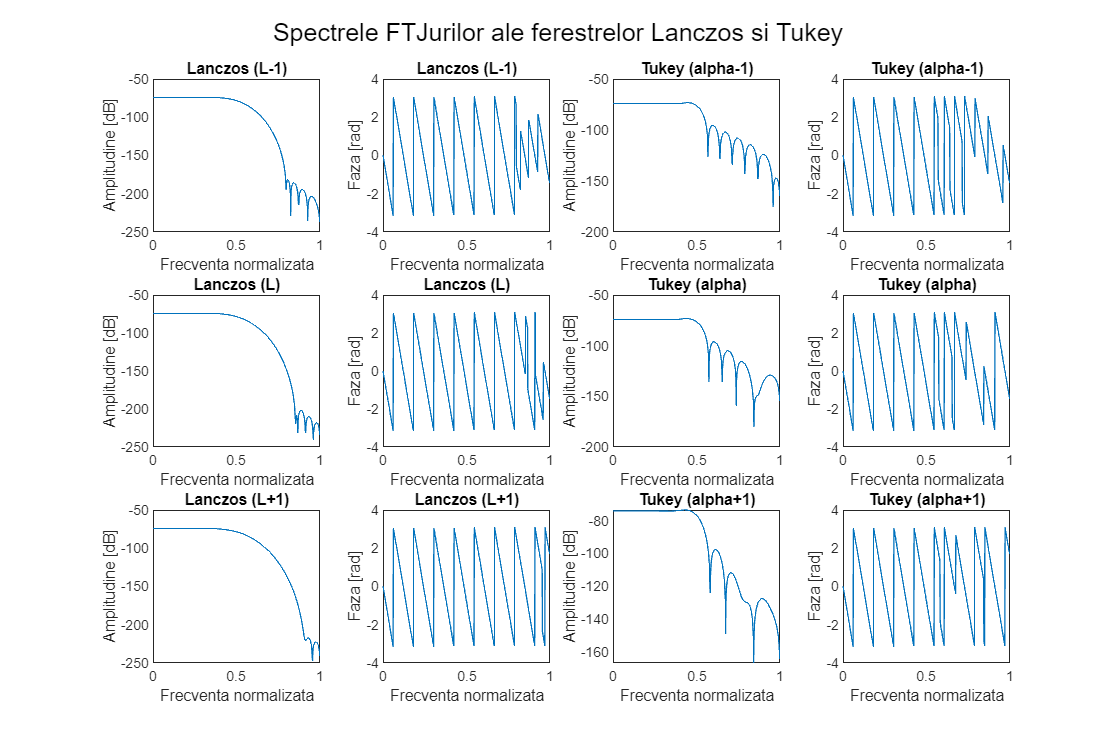

figure(fig12);
subplot(3, 4, 3);
plot(om_inf / pi, mag2db(abs(H_inf)));
title('Tukey (alpha-1)');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(3, 4, 7);
plot(om / pi, mag2db(abs(H)));
title('Tukey (alpha)');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(3, 4, 11);
plot(om_sup / pi, mag2db(abs(H_sup)));
title('Tukey (alpha+1)');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(3, 4, 4);
plot(om_inf / pi, angle(H_inf));
title('Tukey (alpha-1)');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
subplot(3, 4, 8);
plot(om / pi, angle(H));
title('Tukey (alpha)');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
subplot(3, 4, 12);
plot(om_sup / pi, angle(H_sup));
title('Tukey (alpha+1)');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
sgtitle('Spectrele FTJurilor ale ferestrelor Lanczos si Tukey');

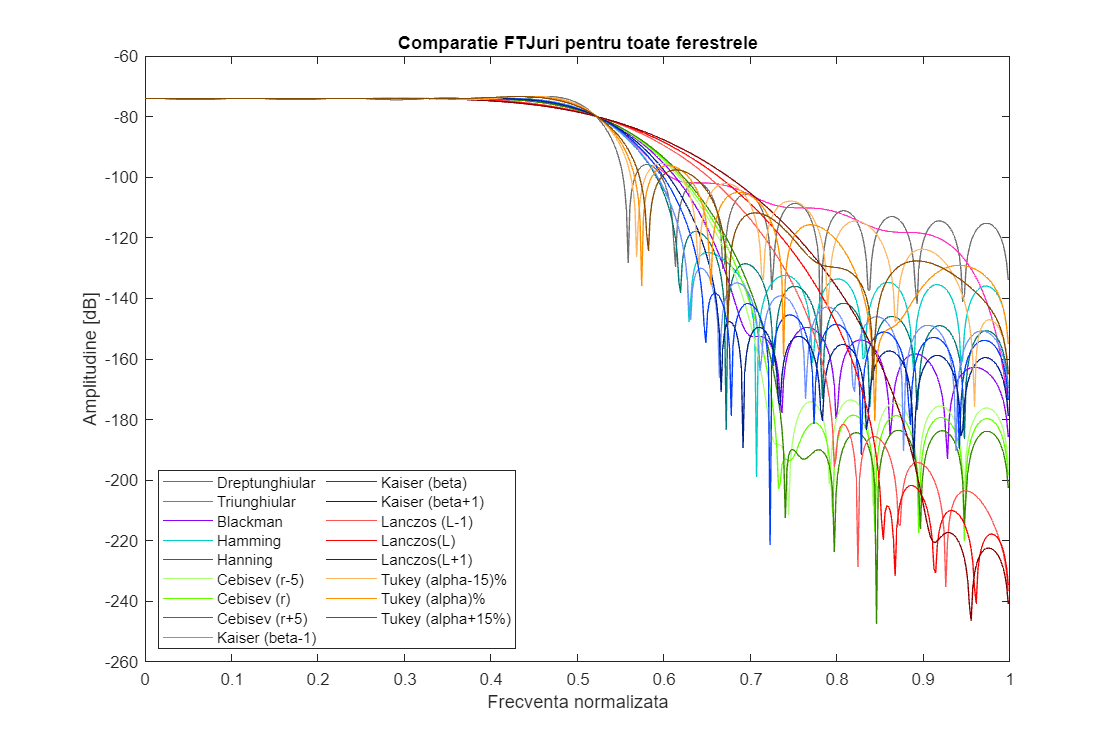

figure(figcompare);
plot(om / pi, mag2db(abs(H_inf)), 'DisplayName', 'Tukey (alpha-15)%', 'Color', '#fcb762');
plot(om / pi, mag2db(abs(H)), 'DisplayName', 'Tukey (alpha)%', 'Color', '#ff9100');
plot(om / pi, mag2db(abs(H_sup)), 'DisplayName', 'Tukey (alpha+15%)', 'Color', '#854900');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
title('Comparatie FTJuri pentru toate ferestrele');
comp_legend = legend('NumColumns', 2, 'Location', 'southwest');
hold off

Cu ajutorul acestui grafic, putem compara si scoate in evidenta caracteristicile ferestrelot folosite pentru a construi FTJurile. Urmatoarea secventa de imagini o sa mareasca portiuni de grafic pentru a scoate in evidenta anumite caracteristici:

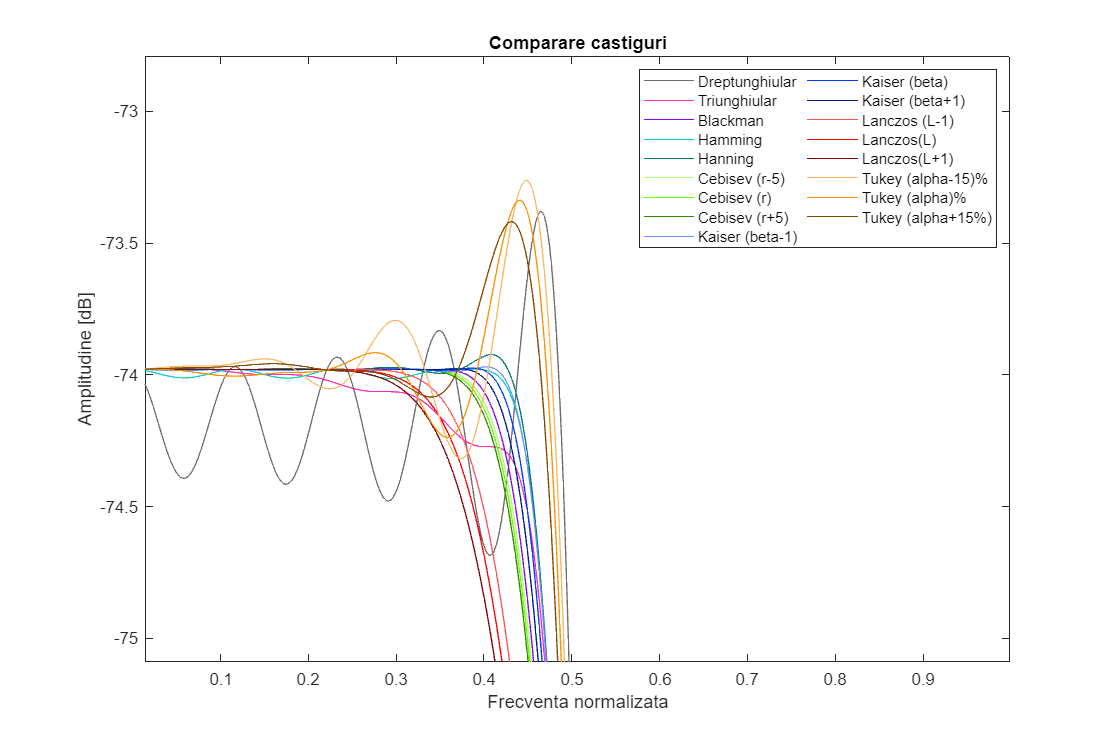

comp_legend.Location = 'northeast';
title('Comparare castiguri');
xlim([0.014 0.999])
ylim([-75.09 -72.79])

Aici putem vedea cel mai bine daca avem oscilatii pe castigul FTJului. Dupa cum observam, majoritatea nu au astfel de probleme, in afara de fereastra dreptunghiulara.

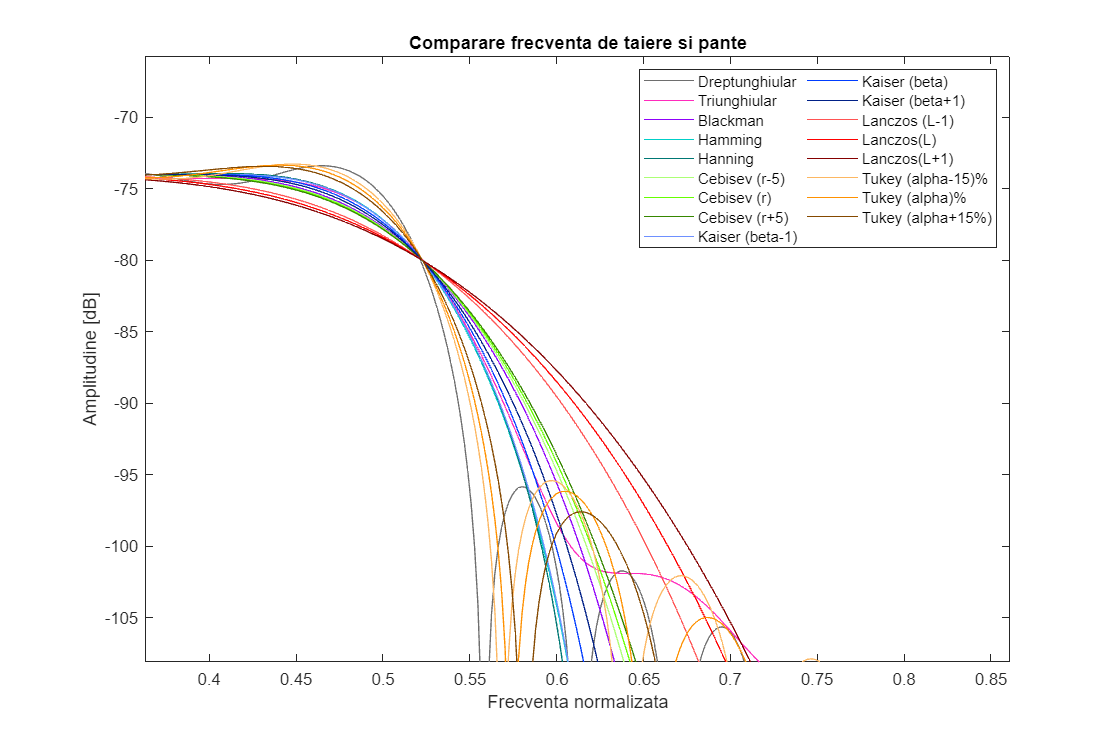

title('Comparare frecventa de taiere si pante');
xlim([0.363 0.861])
ylim([-108.1 -65.7])

Aici putem observa panta filtrelor generate. Lanczos este cel mai putin susceptibil de fenomenul Gibbs (desi pentru toate ferestrele stim care este frecventa de taiere), urmat de Cebisev si Blackman. Cel mai prost la aceasta categorie este, evident, fereastra dreptunghiulara.

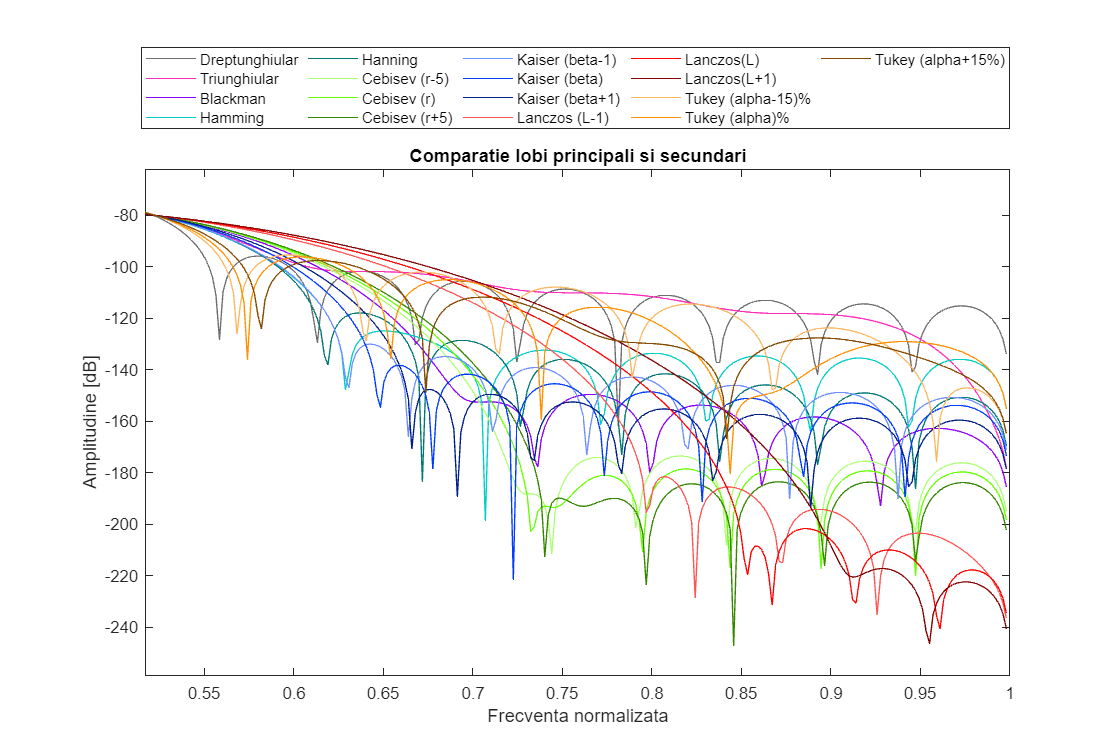

xlim([0.517 1.000])
ylim([-259 -62])
comp_legend.NumColumns = 5;
comp_legend.Location = 'northoutside';
title('Comparatie lobi principali si secundari');

Aici nu mai avem un castigator clar, pentru ca avem multe criterii care trebuie a fi indeplinite pentru lobii principali si secundari, iar filtrele nu pot fi obiectiv bune din toate punctele de vedere. Dupa principiul lui Gabor-Heisenberg, atenuarea amplitudinii lobilor secundari induce cresterea lobului principal in latime, comportament ceea ce nu poate fi prevenit. De asemenea, inca un comportament de observat este ca cu cat panta este mai mare, cu atat lobul principal are o amortizare a inaltimii mai buna (dar sufera intrucat latimea este mai mare). Putem a incepe prin a spune care dintre ferestre sunt slabe in micsorarea lobilor secundari:

- dreptunghiular: atenuarea lobilor principali este infima, se observa intrucat are o panta infima;

- triunghiular: asemanator cu dreptunghiular; ar trebui de precizat ca pe grafic filtrul apare intr-o forma ciudata fata de ce este expus in materialul de curs (presupun ca i se datoreaza ordinului mic);

- Tukey (toate): forma lui este imprevizibila, variaza in functie de parametrul $\alpha$ foarte mult si are oricum o aternuare mica.

Aici totusi putem observa si lobul principal fiind cel mai ingust (dar nu este prea inalt, din cauza pantei). Tukey cu $\alpha \approx 52\%$ este cel mai bun din punctul asta de vedere.

Apoi avem ferestrele cu aternuarea lobilor secundari cea mai pronuntata:

- Cebisev: ar fi al doilea cel mai bun din acest punct de vedere, cu a doua cea mai mica panta (deci lob principal foarte lat); putem observa ca fata de alte filtre, locul de unde porneste si se creeaza lobul secundar are un caracter neuniform;

- Lanczos: are cea mai mica panta, atenuarea lobului principal este de asemenea mai mica decat Cebisev; caracterul lobilor secundari este neuniforma pe tot parcursul lor; fata de Cebisev, unde termenul "r" nu a creat variatiuni mari, parametrul de deschidere a ferestrei (L) variaza considerabil panta, adica cresterea lui micsoreaza panta.

Au ramas ferestrele care au o performanta echilibrata intre taierea rapida a frecventelor mari si atenuarea lor considerabila:

- Hamming: are cei mai mare lobi secundari, dar lob principal ingust;

- Hanning: asemanator cu Hamming, sacrifica din inaltimea lobului principal pentru a scurta lobii secundari;

- Blackman: o scadere lenta a lobului principal ofera lobi secundari scunzi; in zona tranzitorie se observa o trecere lenta catre banda de stop, primul lob secundar nu are o amortizare atat de buna;

- Kaiser: in functie de parametrul $\beta$, se observa cel mai bine fenomenul Gabor-Heisenberg; cresterea lui $\beta$ determina largirii lobului principal, dar descresterea celor secundari; pentru $\beta-1$observam ca are o performanta asemanatoare pentru lobul principal ca Hamming, dar scadere mai buna pe lobii secundari; pentru $\beta+1$avem cea mai mare scadere, cu lobii principali ajungand apropiati de nivelul la care sunt pentru filtrul folosind Blackman.

Dupa ce am prezentat fiecare filtru, facand comparatiile necesare, vom alcatui o clasificare pe baza graficelor:

- Kaiser ($\beta+1$)

- Kaiser ($\beta$)

- Blackman

- Cebisev (r-5)

- Cebisev (r+5)

- Cebisev (r)

- Kaiser ($\beta-1$)

- Hanning

- Lanczos (L-1)

- Hamming

- Lanczos (L)

- Lanczos (L+1)

- Tukey $\alpha\%$

- Tukey $\alpha+15\%$

- Tukey $\alpha-15\%$

- triunghiular

- dreptunghiular

Avand in vedere clasificarile ferestrelor, e timpul sa prezentam si un clasament al lor, in ordine de la cel mai bun la cel mai slab:

- Kaiser: prin variatia parametrului $\beta$ avem controlul cel mai mare asupra modalitatii in care vrem filtrul sa functioneze, fiind cel mai echilibrat dintre toate cele 4 (in comparatie cu Hamming, Hanning, Blackman);

- Blackman: este similar cu Kaiser ca performanta, doar ca nu se poate modifica performanta lui (decat daca folosim un ordin mai mare pentru fereastra, ceea ce nu este cazul pentru acest punct);

- Cebisev: chiar daca lobul principal este mai lat decat alte filtre, acea energie se duce catre scaderea lobilor secundari, care este previzibila si regulata;

- Hanning: are o atenuare a lobilor secundari similara cu Kaiser, cu o latime mica a lobului principal, dar cu o inaltime de asemenea mica; locul lui in clasament este dat datorita faptului ca ar putea fi ales $\beta$ ca sa ajunga similar lui Hanning, devenind redundant;

- Lanczos: are lobii secundari cel mai mici, problema in schimb vine de la faptul ca atenuarea este prea lenta, chiar si cu o deschidere a ferestrei mica; in cazul de fata $L=6$, este posibil pt L mai mic (3, 4) sa avem rezultate mai bune;

- Hamming: similar cu Hanning, doar ca are performante mai slabe;

- Tukey: are atenuarea cea mai rapida, dar performantele slabe pentru lobii secundari si iregularitatea lui il fac sa fie o alternativa slaba fata de restul;

- triunghiular: pe grafic are o performanta foarte proasta; asta presupun ca i se datoreaza ordinului prea mic dat pentru aceasta fereastra;

- dreptunghiular: pe departe cel mai prost; este printre singurele care are si oscilatii pe portiunea de banda de trecere; lobi secundari cu cea mai mica estompare a amplitudinii.

Trebuie luat in vedere ca acest clasament este subiectiv, si ca ordinul pentru care a fost calculat este destul de mic. Diferentele intre cele 2 clasamente este datorat si criteriului diferit de evaluare (aici a fost folosita filtrul generat de o fereastra, in quiz a fost folosit doar spectrul ferestrei).

## Punctul b)

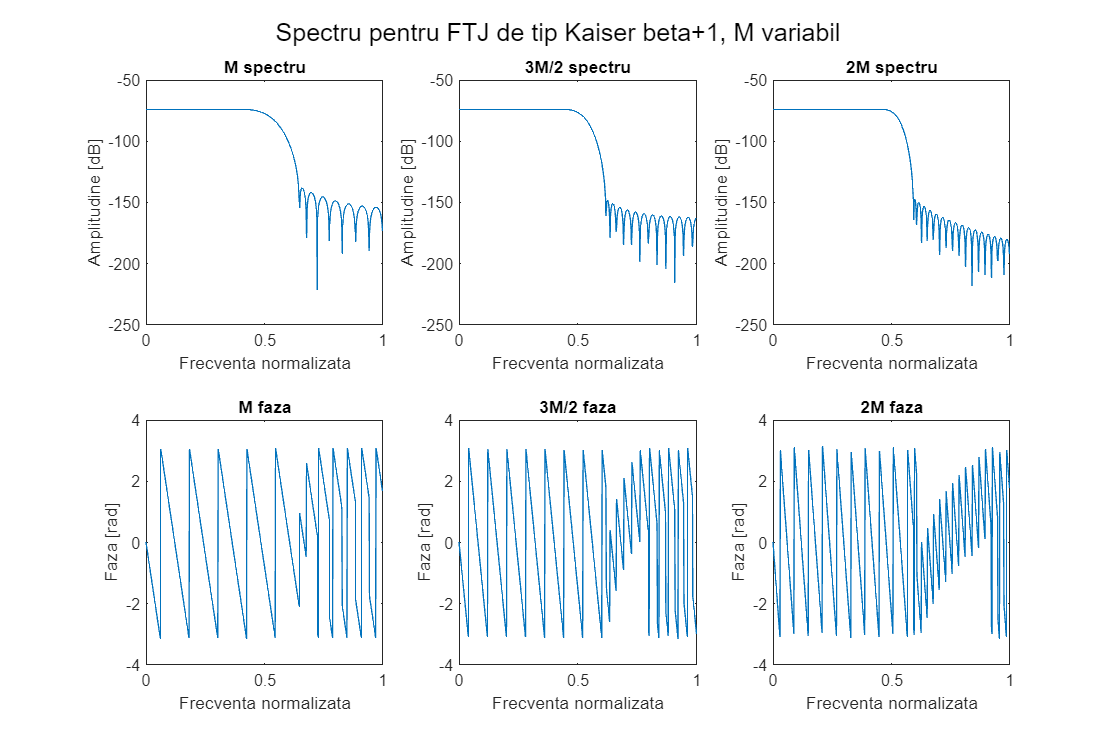

fig2_b = figure('Name', 'Comparatie spectre Kaiser si Lanczos');
% Cea mai buna fereastra
fig13 = figure('Name', 'Spectrul FTJ pentru Kaiser beta+1');
w_kaiser_3div2 = kaiser(window_length * 3 / 2, beta_k + 1);
w_kaiser_3div2 = w_kaiser_3div2 / sum(w_kaiser_3div2);
w_kaiser_2 = kaiser(window_length * 2, beta_k + 1);
w_kaiser_2 = w_kaiser_2 / sum(w_kaiser_2);
h = fir1(window_length - 1, freq_c, w_kaiser);
h_3div2 = fir1(window_length * 3 / 2 - 1, freq_c, w_kaiser_3div2);
h_2 = fir1(window_length * 2 - 1, freq_c, w_kaiser_2);
[H, om] = freqz(h, freqz_rez);
[H_3div2, om_3div2] = freqz(h_3div2, freqz_rez);
[H_2, om_2] = freqz(h_2, freqz_rez);
subplot(2, 3, 1);
plot(om / pi, mag2db(abs(H)));
title('M spectru');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(2, 3, 2);
plot(om_3div2 / pi, mag2db(abs(H_3div2)));
title('3M/2 spectru');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(2, 3, 3);
plot(om_2 / pi, mag2db(abs(H_2)));
title('2M spectru');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(2, 3, 4);
plot(om / pi, angle(H));
title('M faza');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
subplot(2, 3, 5);
plot(om_3div2 / pi, angle(H_3div2));
title('3M/2 faza');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
subplot(2, 3, 6);
plot(om_2 / pi, angle(H_2));
title('2M faza');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
sgtitle('Spectru pentru FTJ de tip Kaiser beta+1, M variabil');

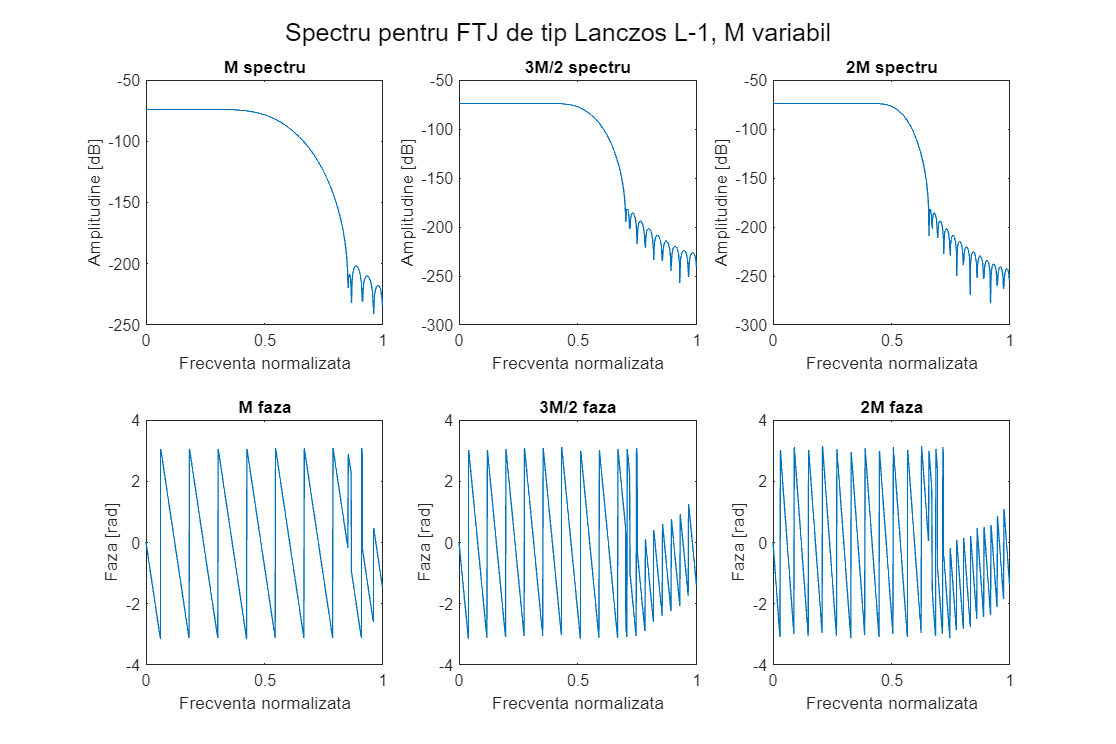

figure(fig2_b);
plot(om / pi, mag2db(abs(H)), 'DisplayName', 'Kaiser M', 'Color', '#6e90ff');
hold on
plot(om / pi, mag2db(abs(H_3div2)), 'DisplayName', 'Kaiser 3/2 * M', 'Color', '#003cff');
plot(om / pi, mag2db(abs(H_2)), 'DisplayName', 'Kaiser 2M', 'Color', '#002087');
% Fereastra de pe locul 9
fig14 = figure('Name', 'Spectrul FTJ pentru Lanczos L-1');
w_lanczos_3div2 = lanczoswin(3 * window_length / 2 + 1, L - 1);
w_lanczos_3div2 = w_lanczos_3div2 / sum(w_lanczos_3div2);
w_lanczos_2 = lanczoswin(window_length * 2, L - 1);
w_lanczos_2 = w_lanczos_2 / sum(w_lanczos_2);
h = fir1(window_length - 1, freq_c, w_lanczos);
h_3div2 = fir1(window_length * 3 / 2, freq_c, w_lanczos_3div2);
h_2 = fir1(window_length * 2 - 1, freq_c, w_lanczos_2);
[H, om] = freqz(h, freqz_rez);
[H_3div2, om_3div2] = freqz(h_3div2, freqz_rez);
[H_2, om_2] = freqz(h_2, freqz_rez);
subplot(2, 3, 1);
plot(om / pi, mag2db(abs(H)));
title('M spectru');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(2, 3, 2);
plot(om_3div2 / pi, mag2db(abs(H_3div2)));
title('3M/2 spectru');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(2, 3, 3);
plot(om_2 / pi, mag2db(abs(H_2)));
title('2M spectru');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
subplot(2, 3, 4);
plot(om / pi, angle(H));
title('M faza');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
subplot(2, 3, 5);
plot(om_3div2 / pi, angle(H_3div2));
title('3M/2 faza');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
subplot(2, 3, 6);
plot(om_2 / pi, angle(H_2));
title('2M faza');
xlabel('Frecventa normalizata');
ylabel('Faza [rad]');
sgtitle('Spectru pentru FTJ de tip Lanczos L-1, M variabil');

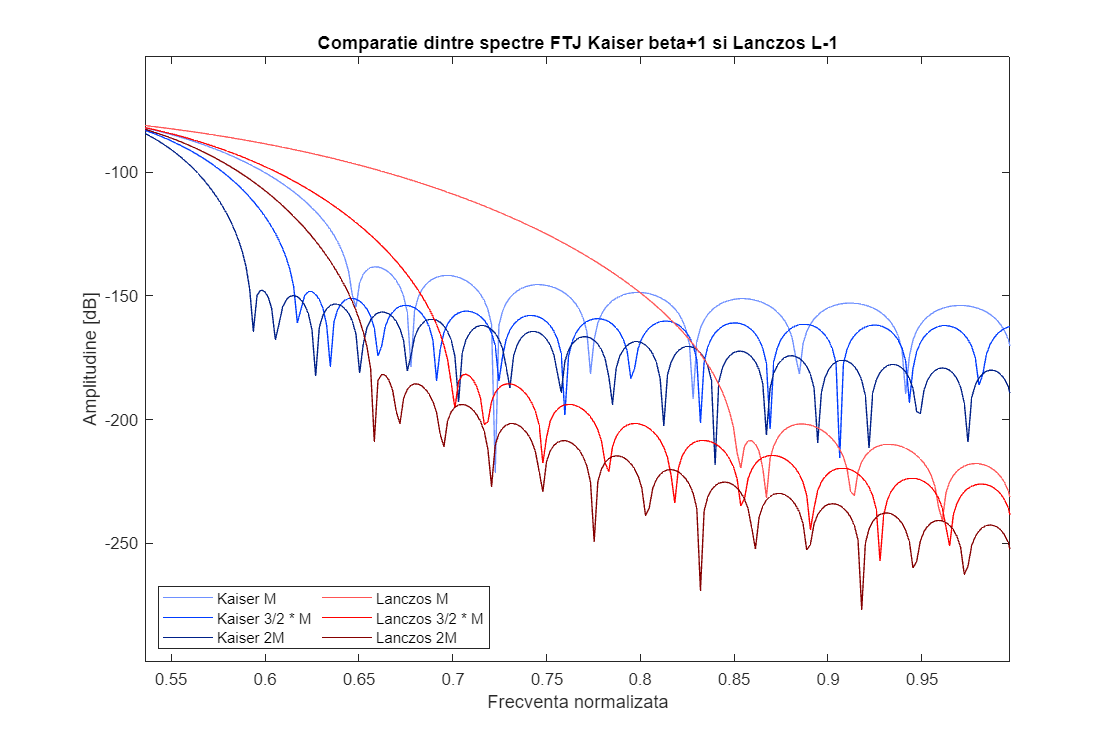

figure(fig2_b);
plot(om / pi, mag2db(abs(H)), 'DisplayName', 'Lanczos M', 'Color', '#ff5454');
plot(om / pi, mag2db(abs(H_3div2)), 'DisplayName', 'Lanczos 3/2 * M', 'Color', '#ff0000');
plot(om / pi, mag2db(abs(H_2)), 'DisplayName', 'Lanczos 2M', 'Color', '#850000');
title('Comparatie dintre spectre FTJ Kaiser beta+1 si Lanczos L-1');
xlabel('Frecventa normalizata');
ylabel('Amplitudine [dB]');
comp2_legend = legend('NumColumns', 2, 'Location', 'southwest');
hold off
xlim([0.536 0.997])
ylim([-298 -53])

Se observa cum cresterea ordinului ferestrei ii creste si calitatea filtrului generat. Daca ar fi sa comparam Lanczos cu fereastra de ordin 2M si Kaiser cu fereastra de ordin M, se observa ca desi Lanczos are lobul principal putin mai lat, el castiga in inaltime, iar lobii secundari sunt mult mai scunzi, drept dovada ca marirea ordinului poate genera filtre superioare.

% Salvam fereastra Kaiser (beta+1) pentru urmatoarea faza.
save('best_window_step3.mat', 'w_kaiser_sup', 'w_kaiser_3div2', 'w_kaiser_2', 'window_length', 'freq_c');

Urmatoarea parte este prezentata in "faza3.mlx".